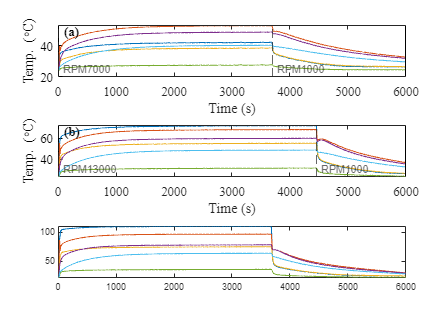

K=[1,2];
load("K_results.mat");
load("20.mat");
tBG=BG;
tBG.K2T=tBG.Out2T(K,:);
%tBG.Out2T(K,:)=[];
index=0;
sp=[1000;6000;12000;18000];
tp=[100;80;40;20];
% %X->C_
% nC_=size(tBG.C_,1);
% for i=1:nC_
%     tBG.C_{i,2}=10.^X(index+i)*tBG.C_{i,2};
% end
% index=index+nC_;

%X->R_
nR_=size(tBG.R_,1);
for i=1:nR_
    tBG.R_{i,3}=10.^X(index+i)*tBG.R_{i,3};
end
index=index+nR_;

%X->Se_
nSe_=size(tBG.Se_,1);
for i=1:nSe_
    tBG.Se_{i,3}=10.^X(index+i)*tBG.Se_{i,3};
end
index=index+nSe_;

%X->S
for i=1:nR_
    if tBG.R_{i,4}>=1e-6
        index=index+1;
        tBG.R_{i,4}=tBG.R_{i,4}*10.^X(index);
    end
end
for i=1:nSe_
    if tBG.Se_{i,4}>=1e-6
        index=index+1;
        tBG.Se_{i,4}=tBG.Se_{i,4}*10.^X(index);
    end
end

%X->RPM_
% nTarget=size(targetSelect,2);
% tBG.RPM_=zeros(nTarget+1,6);
% tBG.RPM_(1,1)=1000;
% tBG.RPM_(1,2:6)=10.^X((1:5)+index);
% index=index+5;
% for i=1:nTarget
%     tBG.RPM_(i+1,1)=(targetSelect(i)+1)*1000;
%     tBG.RPM_(i+1,2:6)=10.^X((1:5)+index);
%     index=index+5;
% end

% nBearing=size(tBG.K_bearing,1);
% for i=1:nBearing
%     length=size(tBG.K_bearing{i,2},2);
%     tBG.K_bearing{i,2}=X((1:length)+index);
%     if isPlot
%         figure;
%         T=20:20:80;
%         n=1000:1000:20000;
%         for t=T
%             y=n;
%             for j=1:20
%                 y(j)=PowerBearing(n(j),t,tBG.K_bearing{i,2});
%             end
%             plot(n,y);
%             hold on;
%         end
%     end
%     index=index+length;
% end

nBearing=size(tBG.K_bearing,1);
for i=1:nBearing
%     length=9;
%     tBG.K_bearing{i,2}=RegressMap2([1000;10000;20000],[100;60;20],X((1:length)+index)');
    length=16;

    tBG.K_bearing{i,2}=RegressMap3(sp,tp,tBG.K_bearing{i,2}(:).*10.^X((1:length)+index)');
    index=index+length;
end

nMotor=size(tBG.K_motor,1);
p={'*','o','s'};
l={'-','--',':'};
for i=1:nMotor
    length=size(tBG.K_motor{i,2},2);
    y=zeros(length,1);
    x=sp;
    dy=tBG.K_motor{i,2}.*10.^X((1:4)+index);
    y(1)=dy(1);
    for j=2:length
        y(j)=y(j-1)+dy(j);
    end
    tBG.K_motor{i,2}=polyfit(x,y,length-1);%3次拟合 降幂排列
    index=index+4;
end

length=size(tBG.K_h,2);
y=zeros(length,1);
x=sp;
dy=tBG.K_h.*10.^X((1:4)+index);
y(1)=dy(1);
    for j=2:length
        y(j)=y(j-1)+dy(j);
    end
tBG.K_h=polyfit(x,y,length-1);%3次拟合 降幂排列
index=index+4;

%X->N
tBG.N=tBG.N.*10.^X((index+1):end);

targetselect=[6:6:18];

figure;
tBG.OutS={'b1';'b2';'i1';'i2';'O1';'O2'};
%tBG.OutS={'s1';'s2';'s3';'s4';'s5';'s6';'m'};
%targetselect=1:18;
for i=1:size(targetselect,2)
    subplot(3,1,i);
    [lengeds]=sim_T2(tBG,targets(targetselect(i)));
    yyaxis right;
    ylim([0,2]);
    text(100,1.8,"("+ char(96+i)+")",'fontsize',12,'fontname','times new roman','FontWeight','bold');
    set(gca,'fontsize',12,'fontname','times new roman',"YColor",[0,0,0],"YTick",[]);
end

legend(lengeds);
